# Lab3: Comparison of exponential and running mean for random walk model 

Team1: Dmitry Shadrin and Eugenii Israelit, Skoltech, 08.04.2016 v1

## The objective of this laboratory work is to compare the errors of exponential and running  mean to choose the most effective quasi-optimal estimation method in conditions of uncertainty. 

## Additional important outcome of this exercise is the solution of identification problem of noise statistics that is crucial for reliable estimation.

Exponential Smoothing -

The weight of measurements decreases according to geometric progression or exponential law

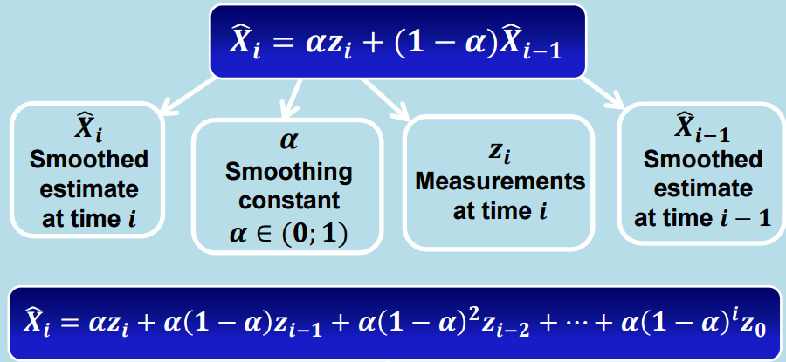

## 1)***Determination of optimal smoothing constant in exponential mean***

Let's Generate a true trajectory $X_i=X_{i-1}+W_i$  using the random walk model 

and Generate measurements  $Z_i$ of the process  $X_i$ , $Z_i=X_i+N_i$, 

where $N_i$ and $W_i$ –normally distributed random noise with zero mathematical expectation and variance  $σ_η^2$ $σ_w^2$.

clc; clear; close all;
set(gcf,'PaperPositionMode','auto');

n=100;
W = normrnd(0,28,1,n);
N = normrnd(0,97,1,n);
X(n) = zeros();
Z(n) = zeros();

X(1)=10;
Z(1)=X(1)+W(1);

for i=2:n
    X(i)=X(i-1)+W(i);
    Z(i)=X(i)+N(i);
end


Let's calculate residual arrays V and R

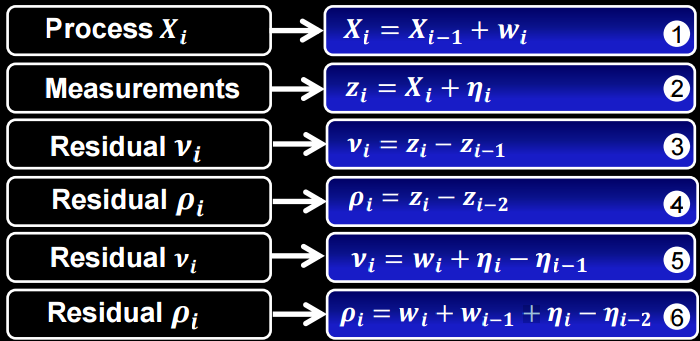

V(n) = zeros();
R(n) = zeros();
SumV=0;
SumP=0;

for i=2:n
    V(i)=(W(i)+N(i)-N(i-1))^2;
end

for i=3:n
    R(i)=(W(i)+W(i-1)+N(i)-N(i-2))^2;
end

V(1)=[];
R(1:2)=[];


Let's Identify of noise statistics $σ_η^2$ and $σ_w^2$ :

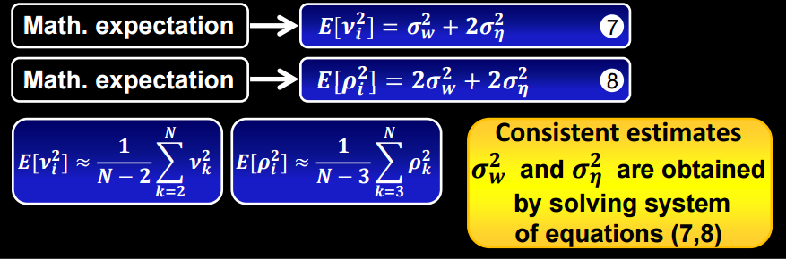

EV=mean(V);
ER=mean(R);

sigmaN = EV - ER/2;
sqrt(sigmaN);

sigmaW = ER - EV;
sqrt(sigmaW);


Let's determine optimal smoothing coefficient in exponential smoothing:

    $α=\frac{-χ+ \sqrt{χ^2+4χ} } {2}$, $ χ=\frac{ σ_w^2  } { σ_η^2 }
$

% x=sigmaW/sigmaN;
x=(28^2)/(97^2);
alpha = (-x+sqrt(x^2+4*x))/2

alpha = 0.2500

Let's Determine the window size  m  (use round values) that provides equality of $σ_{RM}^2$ and $σ_{ES}^2$ using determined smoothing constant  $α$

$σ_{ES}^2=σ_{RM}^2$     =>    $m =   \frac {2-α} {α}$


m = (2-alpha)/alpha

m = 7.0004

nearest_odd_m = 2*floor(m/2)+1

nearest_odd_m = 7

Let's make running mean and exponential Smoothings and Plot the results :

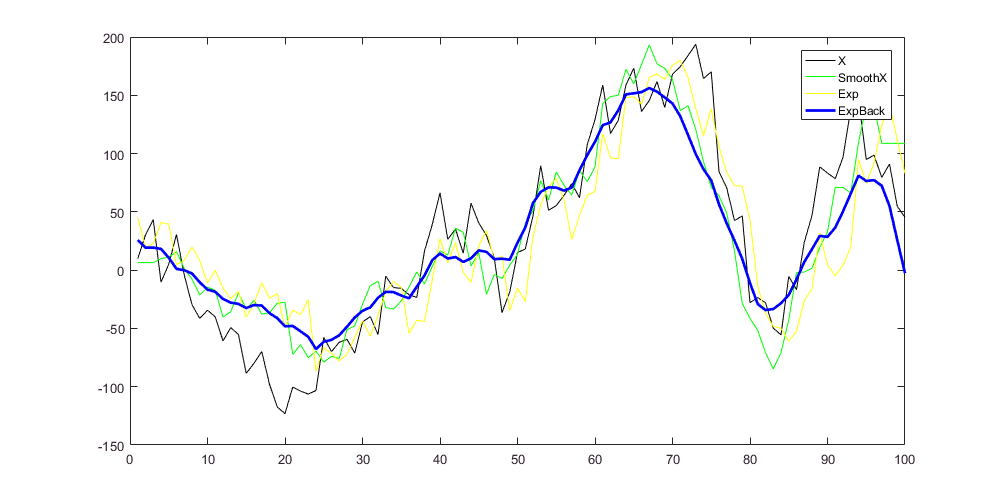

SmoothZ = smooth(Z, nearest_odd_m);
Exp = smoothExp(Z, alpha);
ExpBack = smoothExpBack(Z, alpha);


figure('position', [0, 0, 1000, 500]) ; 
plot(X,'black');
hold on;
plot(SmoothZ,'green');
plot(Exp,'yellow');
plot(ExpBack,'blue', 'LineWidth',2);
legend('X','SmoothX','Exp','ExpBack');